clear
load('./traces/input_sets_second_op.mat');


%Get the mean traces by sets of 20
meanTraces = zeros(15,size(traces_Y,2));

for i = 1 : 15 
    meanTraces(i,:)=mean(traces_Y((i-1)*20+1:i*20,:),1);
end

%Calculate euclidean distance with respect to the first average set trace
euclidDistances = zeros(1,14);

for i = 1 : 14
    euclidDistances(i) = norm(meanTraces(1,:)-meanTraces(i+1,:));
end

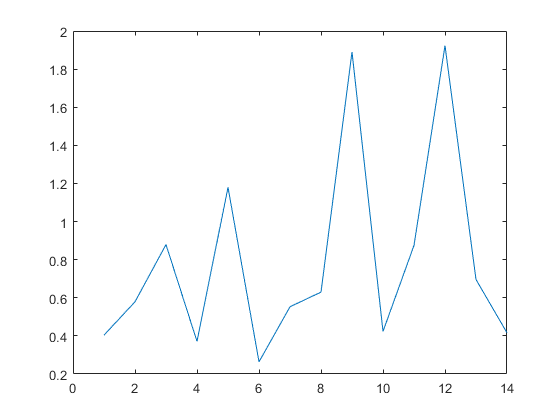

plot(euclidDistances)